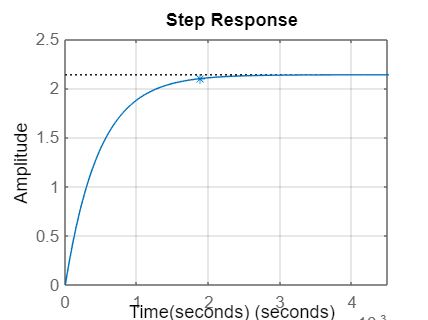

%% 1.
clear variables

R1 = 2.2e3;
R2 = 4.7e3;
R3 = 1e3;
R4 = 1e3;
C1 = 0.1e-6;

k = (R2 / R1) * (R4 / R3);
T = (R2 * C1);

num = [R2 / R1];
den = [R2 * C1 1];
H = tf(num, den);

figure,
hold on,
step(H), plot(4 * T, 0.98 * k, "*");
xlabel('Time(seconds)'), ylabel('Amplitude'); grid;

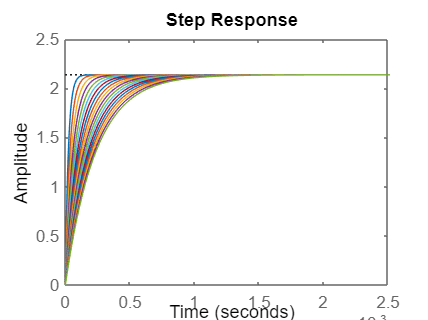


%% 2.

figure,
hold on,
for C1 = 0.005e-6 : 0.0025e-6 : 0.05e-6
    num = [R2 / R1];
    den = [R2 * C1 1];
    H = tf(num,den);
    step(H);
end
hold off;